# 需求分析：区域生长确定目标区域

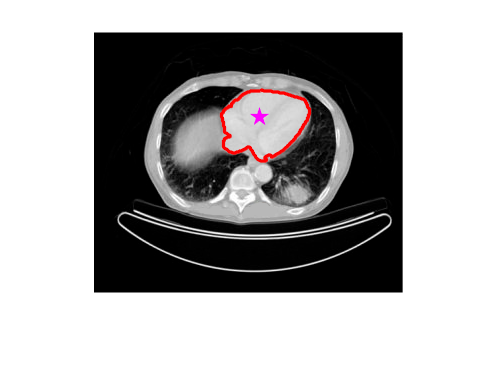

clear;clc;
img = imread('test.bmp');
imshow(img);
% RGB 图转灰度图
if length(size(img)) > 2
    I = rgb2gray(img); 
else
    I = img;
end
% 转成浮点数格式
I = double(I);
% 设置种子点
% p1 = ginput(1);
% x = round(p1(2));
% y = round(p1(1));
x = 85;
y = 166;
% 阈值
threshold = 20;
% 获取 ROI
J = RegionGrowing(I, [x, y], threshold);
% 根据 ROI 确定边界
[bound, F] = RegionBoundary(J);
hold on 
plot(y, x, 'pm', 'MarkerSize', 10, 'MarkerFaceColor', 'm')
plot(bound(:, 1), bound(:, 2), 'r', 'LineWidth', 2)
hold off

function roi = RegionGrowing(imgData, initPos, threshold)
% 区域生长法提取目标区域：比较新像素所在区域平均灰度值与各领域像素的灰度值
% 输入：
%    imgData: 二维数组，数值表示灰度值，0~255
%    initPos: 指定的种子点坐标
%    threshold: 阈值，默认值为20
% 输出：
%   roi: 感兴趣区域
% 输入图像的维数
[row, col] = size(imgData);  
% 输出
roi = zeros(row, col); 
% 初始点
x0 = initPos(1);               
y0 = initPos(2);
% 生长起始点灰度值
regMean = imgData(x0, y0); 
% 生长起始点设置为 1
roi(x0, y0) = 1;       
% 符合生长条件的灰度值总和
regSum = regMean;   
% 符合生长条件的点的个数
regNum = 1;  
% 每次判断周围八个点中符合条件的数目
count = 1;      
% 记录已选择点的坐标
regChoose = zeros(row*col, 2); 
regChoose(regNum, :) = initPos;
num = 1;       % 第一个点   
while count > 0
    % 周围八个点中符合条件的点的灰度值总和
    sTemp = 0;          
    count = 0;
    % 对新增的每个点遍历，避免重复
    for k = 1 : num      
        i = regChoose(regNum - num + k, 1);
        j = regChoose(regNum - num +k, 2);
        % 已确定且不是边界上的点
        if roi(i, j) == 1 && i > 1 && i < row && j > 1 && j < col   
            % 八邻域
            for u =  -1 : 1      
                for v = -1 : 1
                    % 未处理且满足生长条件的点
                    if roi(i + u, j + v) == 0 && abs(imgData(i + u, j + v) - regMean) <= threshold
                        % 对应点设置为 1
                        roi(i + u, j + v) = 1;           
                        count = count + 1;
                        regChoose(regNum + count, :) = [i + u, j + v];
                        % 灰度值存入 sTemp 中
                        sTemp = sTemp + imgData(i + u, j + v);   
                    end
                end
            end
        end
    end
    % 新增的点
    num = count;   
    % 区域内总点数
    regNum = regNum + count; 
    % 区域内总灰度值
    regSum = regSum + sTemp;  
    % 区域灰度平均值
    regMean = regSum / regNum;     
end
end

function [Pm, Fm] = RegionBoundary(Jm)
% 区域生长后确定区域的边界
% 输入：
%    Jm：感兴趣区域值为1，其余部分值为零
% 输出：
%    Pm：边界坐标，第一列为横向，第二列为纵向
%    Fm：边界点
[xlen, ylen] = size(Jm);
Je = zeros(xlen + 2, ylen + 2);   % 防止出现边界问题
for i = 2 : xlen + 1
    for j = 2 : ylen + 1
        Je(i, j) = Jm(i - 1, j - 1);
    end
end
% 标记 Je 中已经选择的边界点
F = zeros(xlen + 2, ylen + 2);      
% 边界坐标
P = zeros((xlen + 2)*(ylen + 2), 2);   
% 确定第一个边界点A，按行选择，从左至右
flag = 0;
for i = 1 : xlen + 2
    for j = 1 : ylen + 2
        if Je(i, j) == 1 
            m = i;     % 初始点
            n = j;
            flag = 1;
            break;
        end
    end
    if flag
        break;
    end
end
% 初始化
i = m;
j = n;
dir = 7;
flag = 1;
count = 0;
% 从初始点开始遍历，直到满足退出条件
while 1   
    xx = i;
    yy = j;
    if mod(dir, 2) == 0
        dir = mod(dir + 7, 8);
    else
        dir = mod(dir + 6, 8);
    end
    switch dir
        case 0
            j = j + 1;
        case 1
            i = i - 1;
            j = j + 1;
        case 2
            i = i - 1;
        case 3
            i = i - 1;
            j = j - 1;
        case 4
            j = j - 1;
        case 5
            i = i + 1;
            j = j - 1;
        case 6
            i = i + 1;
        case 7
            i = i + 1;
            j = j + 1;
    end
    while abs(Je(i, j) - 1) > 0.1
        dir = mod(dir + 1, 8);
        i = xx;
        j = yy;
        switch dir
            case 0
                j = j + 1;
            case 1
                i = i - 1;
                j = j + 1;
            case 2
                i = i - 1;
            case 3
                i = i - 1;
                j = j - 1;
            case 4
                j = j - 1;
            case 5
                i = i + 1;
                j = j - 1;
            case 6
                i = i + 1;
            case 7
                i = i + 1;
                j = j + 1;
        end    
    end
    if flag == 1
        p = i;
        q = j;
        xx = i;
        yy = j;
        flag = 0;
    end
    F(i, j) = 1;
    xxx = i;
    yyy = j;
    count = count + 1;
    P(count, 2) = xxx;
    P(count, 1) = yyy;
    if m == xx && n == yy && p == xxx && q == yyy
        break;
    end
end
% 输出的时候还原一下
Fm = F(2 : end - 1, 2 : end - 1);
Pm = P(P(:, 1) > 0, :) - 1;
end